## Task 1

### Exercicio 1

    Generate a matrix with 3 rows and 10,000 columns of random numbers between 0.0 and 1.0 (i.e., each column represents an experiment):

experiments = rand(3,10000);

    Generate a matrix with 3 rows and 10,000 columns with the value 1 if the value of the previous matrix is less than 0.5 (i.e., if it came up heads) or with the value 0 otherwise (i.e., if it came up tails):

tosses = experiments < 0.5; % 0.5 corresponds to the prob. of heads

    Generate a row vector with 10,000 elements with the sum of the values of each column of the previous matrix (i.e., the number of heads in each experiment):

results = sum(tosses);

    Generate a row vector with 10,000 elements with the value 1 when the value of the previous vector is 2 (i.e., if the experiment gave 2 heads) or 0 when it is different from 2:

successes = results == 2;

    Determine the result by dividing the number of experiments with 2 heads by the total number of experiments:

probEx1 = (sum(successes)/10000)*100 %#ok<NASGU>

probEx1 = 37

#### Code 1 - second version

N = 1e4; % number of experiments
p = 0.5; % probability of heads
k = 2; % number of heads
n = 3; % number of tosses
tosses = rand(n,N) < p;
results = sum(tosses);
successes = sum(results == k) ;
probEx1 = (successes/N)*100

probEx1 = 36.5700

    A percentagem média é de 37

### Exercicio 2

a)

experiments = rand(15,10000);
tosses = experiments < 0.5;
results = sum(tosses);
successes = results == 6;
probEx2a = (sum(successes)/10000)*100

probEx2a = 15.7600

b)

experiments = rand(15,10000);
tosses = experiments < 0.5;
results = sum(tosses);
successes = results >= 6;
probEx2b = (sum(successes)/10000)*100

probEx2b = 84.8400

### Exercicio 3

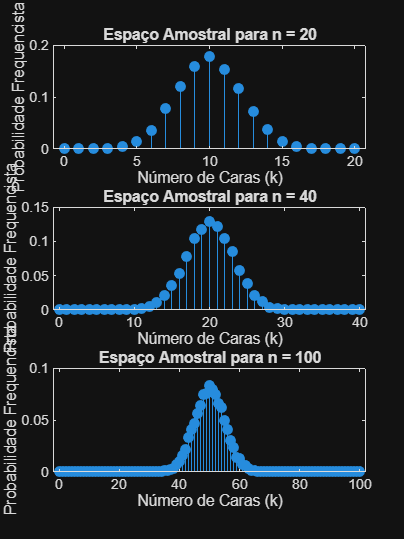

function probSim = estimarProbabilidade(p, n, k, N)
    % p: probabilidade de ser cara
    % n: número de lançamentos por experiência
    % k: número de sucessos desejados
    % N: número de experiências (repetições da simulação)

    % Gera matriz de lançamentos (0 ou 1)
    tosses = rand(n, N) < p;

    % Soma os sucessos em cada experiência (soma ao longo das colunas)
    results = sum(tosses);
    
    % Conta sucessos em cada coluna e verifica se é igual a k
    successes = sum(results == k);
    
    % Calcula a frequência relativa
    probSim = successes / N;
end

% Ex 1: 2 caras em 3 lançamentos
prob_ex1 = estimarProbabilidade(0.5, 3, 2, 10000);

% Ex 2(a): 6 caras em 15 lançamentos
prob_ex2a = estimarProbabilidade(0.5, 15, 6, 10000);

b)

N = 10000; % Número de experiências
p = 0.5;
n_values = [20, 40, 100];

figure('Position', [100, 100, 600, 800]);

ex4_v1 = 0.3750

for i = 1:length(n_values)
    n = n_values(i);
    probs_espaco_amostral = zeros(1, n + 1);
    
    % Calcula a probabilidade para cada número de caras (k de 0 a n)
    for k = 0:n
        probs_espaco_amostral(k + 1) = estimarProbabilidade(p, n, k, N);

ex4_v2 = 0.1527

    end
    
    % Plota o gráfico usando subplot para ficarem os 3 na mesma janela
    subplot(3, 1, i);
    stem(0:n, probs_espaco_amostral, 'filled');
    title(['Espaço Amostral para n = ', num2str(n)]);
    xlabel('Número de Caras (k)');
    ylabel('Probabilidade Frequencista');

ex5_a = 0.9920

end

### Exercicio 4

%% Code 2 - Analytical calculation of probability in series of
% Bernoulli experiments
% Data related to problem 1
p = 0.5;
k = 2;
n = 3;
prob = nchoosek(n,k)*p^k*(1-p)^(n-k); % nchoosek(n,k)= n!/(n-k)!/k!
ex4_v1 = prob

% Data related to problem 2
p = 0.5;
k = 6;

ex5_b = 0.0030

n = 15;
prob = nchoosek(n,k)*p^k*(1-p)^(n-k); % nchoosek(n,k)= n!/(n-k)!/k!
ex4_v2 = prob

### Exercicio 5

a)

p = 10^-5;
k = 0;
n = 100*8;
prob = nchoosek(n,k)*p^k*(1-p)^(n-k);

probAnaliticaEx6A = 0.0081

ex5_a = prob

b)

    Calcular pelo menos 2 erros obriga a somar a probabilidade de ter 2 erros, com a de ter 3, com a de ter 4... até aos 8000 bits. É impraticável.

    A solução inteligente é usar a **Regra do Complemento**: 

    Assim o cenário passa a ser somar **zero erros** ou ter **exatamente 1 erro**. Portanto, calcula-se a probabilidade para k = 0 e para k = 1, somas as duas, e subtrais o resultado a 1.

p = 10^-5;

probSimEx6A = 0.0078

k = 0;
n = 1000*8;
probk0 = nchoosek(n,k)*p^k*(1-p)^(n-k);

k = 1;
probk1 = nchoosek(n,k)*p^k*(1-p)^(n-k);
ex5_b = (1 - (probk1 + probk0)) 

### Exercicio 6

a)

p = 0.1;

probAnaliticaEx6B = 0.9914

k = 3;
n = 5;
probAnaliticaEx6A = binopdf(k,n,p)

% 3 defeitos em 5 escolhidos
probSimEx6A = estimarProbabilidade(0.1, 5, 3, 10000)

b)

% p = 0.1;
% kList = [0 1 2];
% n = 5;
% results = [0 0 0];
% for i = 1:length(kList)
%     k = kList(i);
%     results(i) = binopdf(k,n,p); 
% end

probSimEx6B = 0.9908

% probAnaliticaEx6B = sum(results)

% funçao binocdf faz o mesmo que o codigo acima
probAnaliticaEx6B = binocdf(2, 5, 0.1)

% 2 defeitos, no max, em 5 escolhidos
function probSim = SimEx6B(p, n, k, N)
    % p: probabilidade de acontecer
    % n: número de lançamentos por experiência
    % k: número de sucessos desejados
    % N: número de experiências (repetições da simulação)
    tosses = rand(n, N) < p;
    results = sum(tosses);
    successes = sum(results <= k);
    probSim = successes / N;
end

probSimEx6B = SimEx6B(p,n,2,10000)

c)

figure; 

% Gera os resultados das 10000 amostras de 5 torneiras
tosses_6c = rand(5, 10000) < 0.1;
resultados_6c = sum(tosses_6c);

% Desenha o histograma convertendo para probabilidade
histogram(resultados_6c, 'Normalization', 'probability');
title('Distribuição de Torneiras Defeituosas (Amostras de 5)');
xlabel('Número de Torneiras Defeituosas');
ylabel('Probabilidade');

## Task 2 - Probability, conditional probability, and independence

### Exercicio 1

a)

probSimEx1A = binocdf(1, 2, 0.5)

b)

Designando o nascimento de um filho por M e uma filha por F.

Pelo menos 1 rapaz => MF ou FM ou MM

MF é a intersecção (“e”) de M no primeiro e F no segundo = ½ * ½

P(MF) + P(MM) + P(FM) = ¾

c)

Para resolver isto analiticamente, preciso da definição de probabilidade condicional:

- **Espaço Amostral Base:** Numa família de 2 filhos, os cenários possíveis são 4: {MM, MF, FM, FF} (M = Masculino, F = Feminino).

- **O Evento Condicionante (****B****):** Sei que "pelo menos um é rapaz". Isto elimina o cenário {FF} do nosso espaço. A probabilidade de isto acontecer, P(B), é 3/4.

- **O Evento Desejado (****A****):** Quero que "o outro também seja rapaz". Ora, se um já é rapaz e o outro também, isso significa que a família tem exatamente 2 rapazes. O único cenário que cumpre isto é {MM}.

- **A Interseção (****A **∩** B****):** A probabilidade de ter 2 rapazes E pelo menos 1 rapaz é, logicamente, apenas a probabilidade de ter 2 rapazes. O cenário é {MM}, logo P(A ∩ B) = 1/4.

Aplicando a fórmula:

P(A|B) =  = 1/3

N = 1e5;                     % Nº de familia
p = 0.5;                     % probabilidade de ser rapaz ou rapariga
matriz = rand(2,N) < p;    % N Familias com 2 filhos
totalM = sum(matriz);        % Quantidade de rapazes
fB = sum(totalM >= 1);       % Familias com 1 ou mais rapazes
fAB = sum(totalM == 2);      % Familias com 2 rapazes

probEx1C = fAB / fB          % Resultado esperado 1/3 ( 0,33333...)

d)

Agora temos a certeza que o primeiro filho é um rapaz, logo destas probabilidades {FF}, {MM}, {FM}, {MF}, só duas é que são validas {MM} e {MF}.

Agora queremos saber a probabilidade de acontecer {MM}, como so há duas hipoteses, essa probabilidade é de 0.5 ( 50% )

N = 1e5;                     % Nº de familias
p = 0.5;                     % probabilidade de ser rapaz ou rapariga
matriz = rand(2,N) < p;    % N Familias com 2 filhos

fB = nnz(matriz(1, :) == 1);                             % Familias em que o primeiro filho é rapaz
fAB = nnz(matriz(1, :) == 1 & matriz(2, :) == 1);        % Familias com 2 rapazes
% A funçao nnz faz uma contagem como o sum, apenas a numeros nao nulos (
% mais eficiente para valores de N grandes)

probEx1D = fAB / fB          % Resultado esperado 1/2 (0.5000)

e)

**A Condição Base ( P(B) )**

Ambas as alíneas começam com a mesma premissa: "Knowing that at least one of the children is a boy...".

- Ou seja, sabemos de antemão que a família tem **>= 1**** rapaz**.

- Se somar-mos os rapazes de cada família de 5 filhos, o universo válido (fB) são todas as famílias onde essa soma é maior ou igual a 1. Ignoramos as famílias com 0 rapazes (só raparigas).

**A Condiçao desejada ( P(A) )**

A pergunta quer a probabilidade de "one of the others (and only one) is also a boy".

- Já sabemos que há 1 rapaz garantido, e queremos que *dos restantes* haja **apenas 1 rapaz**, o que é que isto significa no total da família?

- Significa que queremos as famílias que têm **exatamente 2 rapazes** no total.

- Logo, a interseção (fAB) vai ser a contagem das famílias onde o total de rapazes é exatamente 2.

O espaço amostral total de 5 filhos tem 2^5 = 32 combinações possíveis.

A condição base (fB, pelo menos 1 rapaz) elimina apenas 1 cenário (o caso de serem 5 raparigas). Logo, o teu universo de famílias válidas passa a ter **31 combinações**.

- **Alínea (e) - Exatamente 2 rapazes: **Pela fórmula das combinações (Binomial), o número de formas de ter 2 rapazes em 5 filhos é  = 10. A probabilidade teórica é **10 / 31 approx**** 0.3226**. 

N = 1e5;                     % Nº de familias
p = 0.5;                     % probabilidade de ser rapaz ou rapariga
matriz = rand(5,N) < p;      % N Familias com 5 filhos

fB = sum(sum(matriz) >= 1 );      % Familias em há pelo menos 1 rapaz
fAB = sum(sum(matriz) == 2 );     % Familias com 2 rapazes

probEx1E = fAB / fB          % Resultado esperado 10 / 31 (approx 0.3226)

f)

**Condição desejada ( P(A) )**

A pergunta pede a probabilidade de "at least one of the others is also a boy".

- Usando a mesma lógica: já tens 1 rapaz garantido. Queres que, dos restantes, *pelo menos 1* também seja rapaz.

- No total da família, isto traduz-se em ter **2 ou mais rapazes** (>= 2).

- A tua interseção (fAB) nesta alínea será a contagem de famílias onde o total de rapazes é >= 2.

- **Alínea (f) - Pelo menos 2 rapazes: **Quantas famílias têm pelo menos 2 rapazes? Pela Regra do Complemento: 32 (total) - 1 (0 rapazes) - 5 (exatamente 1 rapaz) = 26 combinações. A probabilidade teórica é **26 / 31 approx 0.8387**.

N = 1e5;                     % Nº de familias
p = 0.5;                     % probabilidade de ser rapaz ou rapariga
matriz = rand(5,N) < p;      % N Familias com 5 filhos

fB = sum(sum(matriz) >= 1 );      % Familias em há pelo menos 1 rapaz
fAB = sum(sum(matriz) >= 2 );     % Familias com 2 rapazes

probEx1F = fAB / fB          % Resultado esperado 26 / 31 (approx$ 0.8387)

### Exercicio 2

a)

"Nenhum alvo é atingido mais do que uma vez". Isto significa que todos os 20 dardos acertaram em 20 alvos **diferentes**. Não houve qualquer colisão.

n = 20;
m = 100;
N = 1e5;

% Matriz de n linhas e N colunas, ordenada por coluna
matriz = sort(randi([1, m], n, N));

% diff calcula as diferenças. Se houver repetidos, haverá zeros.
% all() verifica se TODOS os valores numa coluna são estritamente maiores que 0.
% 'sucessos' será um vetor lógico de 1xN com valor 1 onde não houve repetições.
sucessos = all(diff(matriz) > 0);

% Calcula a probabilidade dividindo as simulações sem colisões pelo total
probEx2A = nnz(sucessos) / N

probEx2A = 0.1320

b)

"Pelo menos 1 alvo é atingido duas ou mais vezes". Isto é exatamente o acontecimento complementar da alínea (a). É o cenário onde há **pelo menos uma colisão**.

n = 20;
m = 100;
N = 1e5;

% Matriz de n linhas e N colunas, ordenada por coluna
matriz = sort(randi([1, m], n, N));

% diff calcula as diferenças. Se houver repetidos, haverá zeros.
% all() verifica se TODOS os valores numa coluna são estritamente maiores que 0.
% 'sucessos' será um vetor lógico de 1xN com valor 1 onde não houve repetições.
sucessos = all(diff(matriz) > 0);

% Calcula a probabilidade dividindo as simulações sem colisões pelo total
probEx2B = nnz(~sucessos) / N

probEx2B = 0.8691

c)

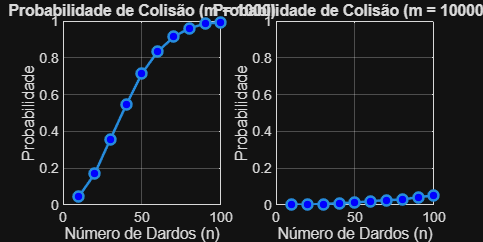

N = 10000;
m_values = [1000, 100000];
n_values = 10:10:100;

figure('Position', [100, 100, 800, 400]); % Cria uma figura larga para os 2 gráficos

for i = 1:length(m_values)
    m = m_values(i);
    probs_colisao = zeros(1, length(n_values)); % Vetor para guardar as probabilidades
    
    for j = 1:length(n_values)
        n = n_values(j);
        
        % 1. Gera a matriz: randi([1, m], n, N) e faz o sort
        % 2. Usa o diff() e o all() para encontrar as colunas SEM colisões
        % 3. Inverte o resultado (usando ~) para encontrar COM colisões
        % 4. Calcula a probabilidade (nnz / N)
        matriz = sort(randi([1, m], n, N));

        sucessos = all(diff(matriz) > 0);
        
        probEx2C = nnz(~sucessos) / N;
        
        probs_colisao(j) = probEx2C;
    end
    
    % Desenha o gráfico na posição 'i' (1 ou 2)
    subplot(1, 2, i);
    plot(n_values, probs_colisao, '-o', 'LineWidth', 1.5, 'MarkerFaceColor', 'b');
    title(['Probabilidade de Colisão (m = ', num2str(m), ')']);
    xlabel('Número de Dardos (n)');
    ylabel('Probabilidade');
    grid on;
    ylim([0 1]); % Força o eixo Y a ir de 0 a 1
end

### Exercicio 3

a)

**O Problema:** Inserir 10 chaves num *array* de tamanho T=1000. Qual a probabilidade de haver *pelo menos* uma colisão?

keys = 10;
T = 1000;
N = 1e5;

% Matriz de n linhas e T colunas, ordenada por coluna
matriz = sort(randi([1, T], keys, N));

sucessos = all(diff(matriz) > 0);

% A probabilidade  que acontece
% pelo menos uma colisão
probEx3A = nnz(~sucessos) / N

probEx3A = 0.0443

b)

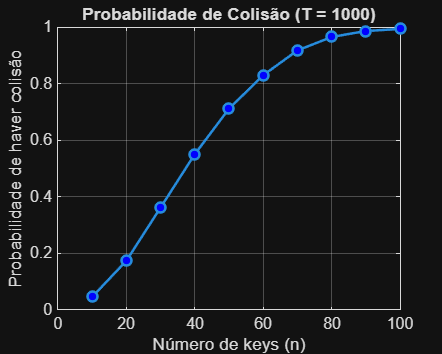

N = 10000;
T = 1000; % Só temos um valor de T
n_values = 10:10:100;

probs_colisao = zeros(1, length(n_values)); % Vetor para guardar as 10 probabilidades

figure('Position', [100, 100, 500, 400]); % Figura normal

for j = 1:length(n_values)
    n = n_values(j);
    
    % Corrigido: usar T em vez de m
    matriz = sort(randi([1, T], n, N));

    sucessos = all(diff(matriz) > 0);
    
    probEx3B = nnz(~sucessos) / N;
    
    probs_colisao(j) = probEx3B;
end

% O plot fica de fora do loop
plot(n_values, probs_colisao, '-o', 'LineWidth', 1.5, 'MarkerFaceColor', 'b');
title(['Probabilidade de Colisão (T = ', num2str(T), ')']);
xlabel('Número de keys (n)');
ylabel('Probabilidade de haver colisão');
grid on;
ylim([0 1]);

c)

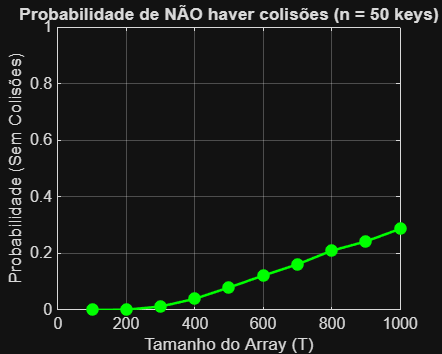

N = 10000;
T_values = 100:100:1000; % Eixo X: O tamanho do array vai variar
n = 50;                  % O número de keys é fixo

% O vetor tem de ter o tamanho dos cenários que vamos testar (os vários T)
probs_sem_colisao = zeros(1, length(T_values)); 

figure('Position', [100, 100, 500, 400]);

for i = 1:length(T_values)
    T = T_values(i);
    
    % 1. Gera a matriz usando o T atual do ciclo e o n fixo
    matriz = sort(randi([1, T], n, N));

    % 2. Encontra colunas SEM colisões
    sucessos = all(diff(matriz) > 0);
    
    % 3. Probabilidade de NÃO HAVER colisões (usamos 'sucessos' e não '~sucessos')
    probEx3C = nnz(sucessos) / N;
    
    % 4. Guarda no vetor
    probs_sem_colisao(i) = probEx3C;
end

% O plot também fica de fora e cruza os T_values com as probabilidades
plot(T_values, probs_sem_colisao, '-o', 'LineWidth', 1.5, 'MarkerFaceColor', 'g', 'Color', 'g');
title('Probabilidade de NÃO haver colisões (n = 50 keys)');
xlabel('Tamanho do Array (T)');
ylabel('Probabilidade (Sem Colisões)');
grid on;
ylim([0 1]);

### Exercicio 4

a)

O guião pede-te para calcular o número mínimo de pessoas numa festa para que a probabilidade de duas ou mais fazerem anos no mesmo dia seja superior a 50%

Matematicamente e em termos de código, **é exatamente o mesmo problema dos dardos (Ex 2) e da *****Hash Table***** (Ex 3)**

- Os "alvos" ou "tamanho do array" (m) agora são os **365 dias do ano**.

- Os teus "dardos" ou "chaves" (n) são o **número de pessoas**.

- A "colisão" é o facto de **duas ou mais pessoas partilharem a data**.

N = 1e5;
dias = 365;

nFinal4A = 0;
nFinal4B = 0;

for n = 2:100   
    matriz = sort(randi([1, dias], n, N));
    sucessos = all(diff(matriz) > 0);
    probEx4 = nnz(~sucessos) / N;

    % Verifica os 50% (só guarda se ainda não tiver guardado antes)
    if probEx4 > 0.5 && nFinal4A == 0
        nFinal4A = n;
        fprintf('Ex4 - (a) - Pessoas necessárias (>50%%): %d\n', nFinal4A);
    end

    % Verifica os 90%
    if probEx4 > 0.9 && nFinal4B == 0
        nFinal4B = n;
        fprintf('Ex4 - (b) - Pessoas necessárias (>90%%): %d\n', nFinal4B);
        break; % Terminar o loop for, pois já encontrou o resultado pretendido
    end
end

Ex4 - (a) - Pessoas necessárias (>50%): 23


Ex4 - (b) - Pessoas necessárias (>90%): 41


### Exercicio 5

O cenário é o lançamento de um dado de 6 faces, duas vezes.

Como trata-se de um dado com números de 1 a 6, a base é voltar a usar a função randi.

    Gerar uma matriz de 2 linhas (os dois lançamentos) e N colunas (as repetições da experiência).

a)

Somar as colunas da matriz e verificas onde o resultado é exatamente 9.

N = 1e5;

matriz = randi([1,6], 2, N);
sucessos = sum(matriz) == 9;
probEx5aA = nnz(sucessos) / N

probEx5aA = 0.1133

É pedido para descobrir apenas se a segunda linha da matriz (`matriz(2, :)`) é par.

    Para saber se um número é par no Matlab, usamos a função de resto da divisão `rem(..., 2) == 0`.

N = 1e5;

matriz = randi([1,6], 2, N);
sucessos = rem(matriz(2,:), 2) == 0;
probEx5aB = nnz(sucessos) / N

probEx5aB = 0.4989

Pelo menos um valor é 5. Podemos usar o `any()` para verificar coluna a coluna se existe algum valor igual a 5

N = 1e5;

matriz = randi([1,6], 2, N);
sucessos = any(matriz == 5);
probEx5aC = nnz(sucessos) / N

probEx5aC = 0.3056

Nenhum valor é 1.

N = 1e5;

matriz = randi([1,6], 2, N);

matriz =      2     1     3     2     6     3     6     1     2     4     4     4     1     3     3     2     1     2     4     3     3     4     1     3     1     1     5     3     6     2     3     4     3     6     6     4     6     6     1     6     5     2     5     3     3     5     4     5     5     4
     6     5     4     5     2     5     4     3     5     6     5     2     1     5     6     3     1     5     5     6     1     2     6     5     4     6     3     3     4     5     3     5     4     4     5     6     3     1     5     5     5     4     4     2     4     1     5     2     2     3


sucessos = any(matriz == 1);

sucessos = 1×100000 logical array
   0   1   0   0   0   0   0   1   0   0   0   0   1   0   0   0   1   0   0   0   1   0   1   0   1   1   0   0   0   0   0   0   0   0   0   0   0   1   1   0   0   0   0   0   0   1   0   0   0   0


probEx5aD = nnz(~sucessos) / N

probEx5aD = 0.6925

b)

Na teoria, a regra matemática para provar que dois acontecimentos X e Y são independentes é verificar se a seguinte igualdade é verdadeira: **P(X e Y) = P(X) * P(Y)**

Para resolver a **alínea (b) é necessário** responder a três perguntas teoricas (sabendo que existem 6 * 6 = 36 combinações possíveis ao lançar dois dados):

**P(A)****:** Quais são os pares cuja soma dá 9? Qual é a probabilidade P(A)?

                 (3,6), (4,5), (5,4), (6,3)

                P(A) = 4/36 = 1/9

**P(B):** Qual a probabilidade de o 2º dado ser par (2, 4 ou 6)?

            P(B) = 3/6 = 1/2

**P(A e B):** Daqueles pares cuja soma dá 9, quantos é que terminam num número par?

            (3,6) e (5,4) isso dá uma probabilidade de 2/32 = 1/18 = P(A e B)

            Como P(A) * P(B) = 1/9 * 1/2 = 1/18 ( igual a P(A e B) ) os eventos A e B são independentes.

c)

**P(C)****:** Pelo menos um é 5?

                Pelo menos um é 5. Os casos são: (5,1), (5,2), (5,3), (5,4), (5,5), (5,6) e ainda (1,5), (2,5), (3,5), (4,5), (6,5). 

                Totaliza **11 casos**. Logo, **P(C) = 11/36**.

**P(D):** Qual de nenhum ser 1?

            Isto significa que o 1º dado tem 5 opções (2 a 6) e o 2º dado também tem 5 opções (2 a 6). No total há 5 * 5 = 25 casos possíveis. Logo, **P(D) = 25/36**.

**P(C e D):** Pelo menos 1 é cinco e o outro nao é 1?

            Queremos as combinações que têm "pelo menos um 5" E que "nenhum valor seja 1". Se olharmos para os 11 casos do Evento C eliminamos o (5,1) e o (1,5). Sobram **9 casos**. Logo, a interseção correta é **P(C e D) = 9/36 = 1/4**.

            P(C) * P(D) = 11/36 * 25/36 = 275 / 1296

            A probabilidade 1/4 = 324 / 1296. Como os valores **são diferentes**, conclui-se que **os eventos C e D NÃO SÃO independentes**.

### Exercicio 6

Este exercicio aplica a **Lei da Probabilidade Total** e o **Teorema de Bayes**

É necessário definir os eventos com base no enunciado:

- **I**: O link está com Interferência. (A probabilidade dada é de 2%, logo P(I) = 0.02).

- **N**: O link está Normal. (Como é o complementar de I, então P(N) = 1 - 0.02 = 0.98).

- **E**: O pacote é recebido com Erro.

Agora, as probabilidades condicionais que o enunciado nos dá:

- Probabilidade de erro *sabendo que* o link está normal: P(E|N) = 0.1% = 0.001.

- Probabilidade de erro *sabendo que* o link tem interferência: P(E|I) = 10% = 0.10.

a)

"Qual a probabilidade de um pacote ser recebido com erros?". Ou seja, queremos calcular apenas o P(E).

- O erro pode vir de duas "fontes" mutuamente exclusivas: ou ocorreu durante o estado normal, ou ocorreu durante o estado de interferência.

- Graças à **Lei da Probabilidade Total** podemos somar a probabilidade de o erro acontecer em cada um dos estados * a probabilidade de esse estado existir.

- Aplicando a fórmula P(E) = P( E | N ) * P(N) + P( E | I ) * P(I).

- P(E) = 0.001 * 0.98 + 0.10 * 0.02 = 0.00298

b) 

Sabendo que tem erro, qual é a probabilidade de a culpa ser da Interferência (**P(I|E)**) e qual a probabilidade de ter sido apenas um azar no estado Normal (**P(N|E)**)?

É possível resolver o exercício pelo **Teorema de Bayes:**

 A formula necessária é esta:

  

P( N | E ) = (0.001 * 0.98) / 0.00298 = 0.3289

P( I | E ) é possivel obter fazendo o complemento de P( N | E ). 

    Logo P( I | E ) = 1 - P( N | E ) = 0.6711

### Exercicio 7

Total de 100 programas

Probabilidade do programa ser do:

- P(Andre) = 20/100 = 0.2

- P(~Andre) = 0.8

- P(Bruno) = 30 / 100 = 0.3

- P(~Bruno) = 0.7

- P(Carlos) = 0.5

- P(~Carlos) = 0.5

Probabilidade de ter erro e ser do:

- P(Erro | Andre) = 0.01

- P(Erro | Bruno) = 0.05

- P(Erro | Carlos) = 0.001

As proximas alineas é tendo em conta que o CEO encontrou erro.

***Dúvida: Porque é que usamos probabilidade condicional e não interseção? Neste caso eu leio como a probabilidade de ter erro e ser do carlos logo P(E e A).***

***Resposta: ***A chave para perceber está na frase "The probability of a program ***from each of them*** having errors..."

**O Cenário da Interseção: ****P(E e C)**

Se o valor 0.001 da tabela fosse a interseção P(E e C), o texto teria de dizer algo como: *"A probabilidade de o CEO escolher um programa ao calhas (do monte total de 100) e esse programa ser do Carlos e ter erro é 0.001"*.

- **O Universo aqui é:** Toda a empresa (100 programas).

**O Cenário da Condicional: ****P(E | C)**

A expressão *"from each of them"* funciona como um filtro. O texto está a dizer-te qual é a "taxa de erro pessoal" do Carlos. Ele não está a olhar para os 100 programas da empresa, está a olhar **apenas para o caso do Carlos**.

- **O Universo aqui é:** Apenas os programas feitos pelo Carlos.

- Traduzindo para português: "Se eu agarrar num programa, **sabendo previamente que é do Carlos**, a probabilidade de ele ter um erro é de 0.001". Isto é a definição exata de probabilidade condicional: P(E|C).

a)

Primeiramente precisamos de determinar o valor de P(E):

Como temos 3 universos:

P(E) = P(E | A) * P(A) + P(E | B) * P(B) + P(E | C) * P(C)

        = 0.01 * 0.2 + 0.05 * 0.3 + 0.001 * 0.5 = 0.0175

P(Carlos | Erro) = (0.001 * 0.5) / 0.0175 = 0.0286

b)

Para esta alinea queremos saber qual o programador mais provavel de aparecer sabendo que ocorreu um erro:

P(A | E) = [ P(E | A) * P(A) ] / P(E)

             = [ 0.01 * 0.2 ] / 0.0175

             = 0.1143

P(B | E) = [ P(E | B) * P(B) ] / P(E)

             = [ 0.05 * 0.3 ] / 0.0175

             = 0.8571

P(C | E) = 0.0286

O programador com mais chance de ser escolhido sabendo que ocorreu erro é o Bruno com 86% de chance.